addpath(genpath('/Users/teatompos/Desktop/Matlab_scripts/RU_1st_internship_Neurophysiology_Dept/DynaSim'))
addpath(genpath('/Users/teatompos/Library/CloudStorage/GoogleDrive-t.tompos@neurophysiology.nl/.shortcut-targets-by-id/1f3yqxuDDFP_-nrGlSKbqcVC3RJJZZWTiWyK5Kl5x65maOi21i1OEIloSOR_UsCfsdiH2FbZf/Lab notebook Tea Tompoš/Thesis/Chapter 6 (Active metaplasticity)'))
addpath(genpath('/Users/teatompos/Documents/GitHub/PhD_Project2--NodesVsEdges'))
addpath(genpath('/Users/teatompos/Library/CloudStorage/GoogleDrive-t.tompos@neurophysiology.nl/.shortcut-targets-by-id/1f3yqxuDDFP_-nrGlSKbqcVC3RJJZZWTiWyK5Kl5x65maOi21i1OEIloSOR_UsCfsdiH2FbZf/Lab notebook Tea Tompoš/Thesis/Chapter 1 (Nodes vs Edges)/Code/functions'));
clear all; close all;

simulations1Path = '/Users/teatompos/Documents/GitHub/Multiple-mediators-Collab/Data/MiniNet';
simulations2Path = '/Users/teatompos/Library/CloudStorage/GoogleDrive-t.tompos@neurophysiology.nl/.shortcut-targets-by-id/1f3yqxuDDFP_-nrGlSKbqcVC3RJJZZWTiWyK5Kl5x65maOi21i1OEIloSOR_UsCfsdiH2FbZf/Lab notebook Tea Tompoš/Thesis/Chapter 3 (Targeted ablation)/Data';

cd(simulations2Path)

## Define LIF params

clearvars -except LIF_* FN_* *Path *Repo LIF_N FN_inputMatrix
LIF_reset = -70;
LIF_threshold = -55;
LIF_rest_range = [-69 -63];
LIF_gain_range = [1.5 3];
LIF_tau = 100;

% synapse strength
LIF_gSyn = 0.3; % ~(0.225/5): 5 presyn AP within 3 ms are needed to trigger 1 postyn AP 

## Define inputs

clearvars -except LIF_* FN_* *Path *Repo

FN_duration = 200; % ms
sampling_rate = 10;     % kHz
FN_dt = 1/sampling_rate; 

FN_scale = 5;
LIF_N = 20;

FN_inputAmp = 120;
LIF_input_probability = 0.25;
stepOnset = 20/FN_dt;
stepOffset = 180/FN_dt;

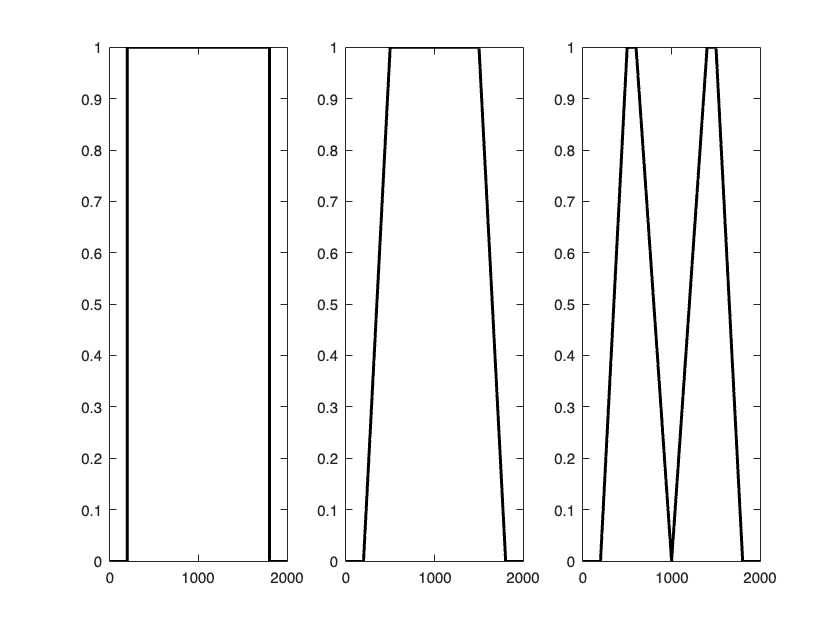

templateInput = zeros(size([0:FN_dt:FN_duration]));

templateInput(stepOnset:stepOffset) = 1;
input1 = templateInput;

templateInput(stepOnset:stepOnset + 30/FN_dt) = linspace(0,1,length(stepOnset:stepOnset + 30/FN_dt));
templateInput(stepOffset - 30/FN_dt:stepOffset) = linspace(1,0,length(stepOffset - 30/FN_dt:stepOffset));
input2 = templateInput;

templateInput(stepOnset + 40/FN_dt:stepOnset + 80/FN_dt) = linspace(1,0,length(stepOnset + 40/FN_dt:stepOnset + 80/FN_dt));
templateInput(stepOffset - 80/FN_dt:stepOffset - 40/FN_dt) = linspace(0,1,length(stepOffset - 80/FN_dt:stepOffset - 40/FN_dt));
input3 = templateInput;

figure; tiledlayout(1,3)
nexttile; plot(input1, 'k', 'LineWidth',2)
nexttile; plot(input2, 'k', 'LineWidth',2)
nexttile; plot(input3, 'k', 'LineWidth',2)


FN_inputMatrix = [input1; input2; input3];

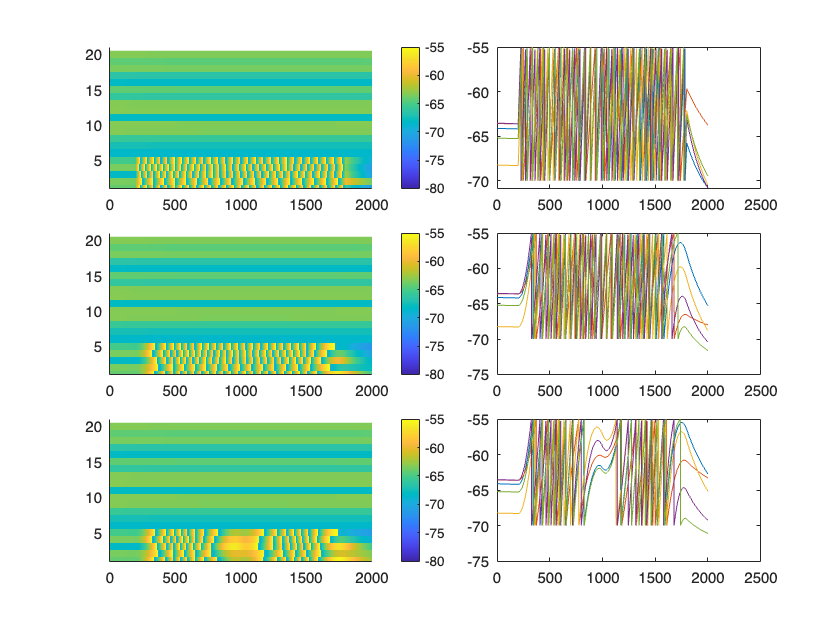

clearvars -except LIF_* FN_* *Path *Repo 
figure; clf; tiledlayout(3,2); 

LIF_rest = single(rand(LIF_N,1) .* (LIF_rest_range(end) - LIF_rest_range(1)) + LIF_rest_range(1))';
LIF_gain = single(rand(LIF_N,1) .* (LIF_gain_range(end) - LIF_gain_range(1)) + LIF_gain_range(1))';

input_connectivity = zeros(LIF_N,1);
input_connectivity(1:round(LIF_N*LIF_input_probability)) = 1;

for inputIdx = 1:size(FN_inputMatrix,1)
    MiniNetwork = [];
    input_mat = (repmat(FN_inputMatrix(inputIdx,:)*FN_inputAmp, LIF_N,1) .* input_connectivity);

    % network setup
    MiniNetwork.populations(1).name = 'E';
    MiniNetwork.populations(1).size = LIF_N;
    MiniNetwork.populations(1).equations = 'AgnesVogels2024_LIF';                                % leaky integrate-and-fire modified by TTompos
    MiniNetwork.populations(1).mechanism_list = {'TimeVaryingSignal'};
    MiniNetwork.populations(1).parameters = {...
        'reset', LIF_reset, 'thresh', LIF_threshold, 'R', LIF_gain, 'tau', LIF_tau, 'E', LIF_rest, ...         % LIF-related
        'signal', input_mat', 'EndTime',FN_duration, ...           % input-related
        };
    
    MiniNetwork = dsCombineSpecifications(MiniNetwork);
    results = dsSimulate(MiniNetwork, 'tspan', [0 FN_duration], 'dt',FN_dt);
    
    
    
    nexttile; hold on
    imagesc(results.E_V')
    colormap(gca,parula);
    clim([-80 -55])
    colorbar
    xlim([0 length(results.time)])
    ylim([1 LIF_N+1])
    
    nexttile;
    plot(results.E_V(:,1:5))
end

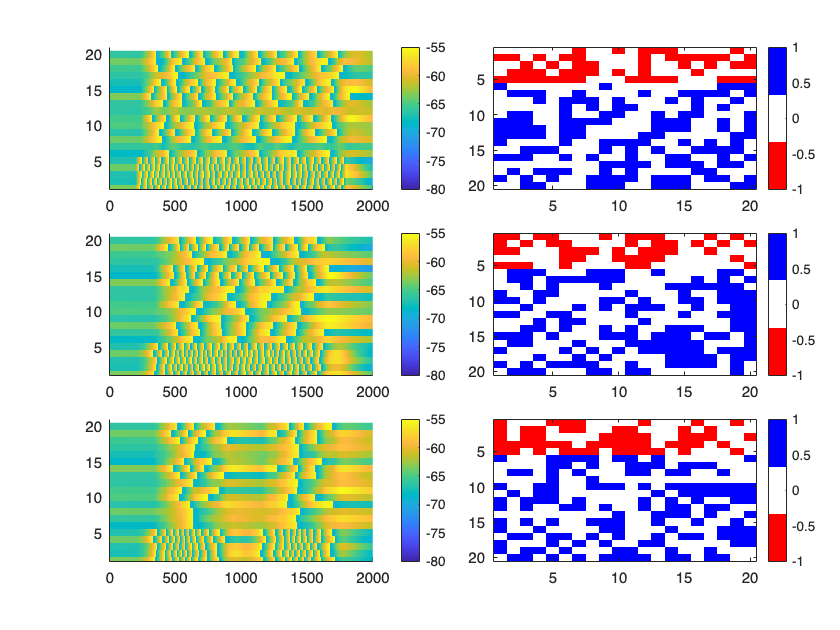

clearvars -except LIF_* FN_* *Path *Repo
figure; clf; tiledlayout(3,2); 

LIF_rest = single(rand(LIF_N,1) .* (LIF_rest_range(end) - LIF_rest_range(1)) + LIF_rest_range(1))';
LIF_gain = single(rand(LIF_N,1) .* (LIF_gain_range(end) - LIF_gain_range(1)) + LIF_gain_range(1))';

input_connectivity = zeros(LIF_N,1);
input_connectivity(1:round(LIF_N*LIF_input_probability)) = 1;

firstLayer = sum(input_connectivity>0);
secondLayer = sum(input_connectivity==0);

sparseLevel = 0.5;
inhRatio = 0.2;

for inputIdx = 1:size(FN_inputMatrix,1)
    MiniNetwork = [];
    input_mat = (repmat(FN_inputMatrix(inputIdx,:)*FN_inputAmp, LIF_N,1) .* input_connectivity);

    % network setup
    MiniNetwork.populations(1).name = 'E';
    MiniNetwork.populations(1).size = LIF_N;
    MiniNetwork.populations(1).equations = 'AgnesVogels2024_LIF';                                % leaky integrate-and-fire modified by TTompos
    MiniNetwork.populations(1).mechanism_list = {'TimeVaryingSignal'};
    MiniNetwork.populations(1).parameters = {...
        'reset', LIF_reset, 'thresh', LIF_threshold, 'R', LIF_gain, 'tau', LIF_tau, 'E', LIF_rest, ...         % LIF-related
        'signal', input_mat', 'EndTime',FN_duration, ...           % input-related
        };

    MiniNetwork.connections(1).direction='E->E';
    MiniNetwork.connections(1).mechanism_list = 'iampa';
    
    iNeurons = round(secondLayer*inhRatio);
    M = ones(LIF_N,LIF_N) - eye(LIF_N,LIF_N);
    if iNeurons>0
        % M(1:iNeurons, :) = M(1:iNeurons, :)*-1;
        M(end-iNeurons-1:end, :) = M(end-iNeurons-1:end, :)*-1;
    end
    M_sparse = M;
    
    % sparsification protocol
    remove_edge_num = round(numel(find(M_sparse~=0))*sparseLevel);
    if remove_edge_num>0
        idx_array = 1:size(M_sparse,1)*size(M_sparse,2);
        new_array = idx_array(~ismember(idx_array,find(M_sparse==0)));
        permutation = randperm(length(new_array)); % generate permutation indices
        permuted_array = new_array(permutation);
        random_edge = permuted_array(1:remove_edge_num);
        M_sparse(random_edge) = 0;
    end
    M = M_sparse;

    MiniNetwork.mechanisms(1).name='iampa';
    MiniNetwork.mechanisms(1).equations={
          ['gSYN=' num2str(LIF_gSyn)]
          'ESYN=0; tauD=4; tauR=0.4; delay=0'
          'netcon=zeros(N_pre, N_post)'
          'f(x) = 1*(exp(-x/tauD)-exp(-x/tauR)).*(x>0)'
          'Isyn(V_post) = gSYN.*(sum(f(t-tspike_pre-delay))*netcon).*(V_post-ESYN)'
          '@current += -Isyn(V_post)'
          'monitor Isyn'
        }; 
    MiniNetwork.connections(1).parameters={'netcon', M};
    
    MiniNetwork = dsCombineSpecifications(MiniNetwork);
    results = dsSimulate(MiniNetwork, 'tspan', [0 FN_duration], 'dt',FN_dt);
  
    nexttile; hold on
    imagesc(results.E_V')
    colormap(gca,parula);
    clim([-80 -55])
    colorbar
    xlim([0 length(results.time)])
    ylim([1 LIF_N+1])
    
    nexttile;
    imagesc(flipud(results.model.fixed_variables.E_E_iampa_netcon))
    if any(any(M<0))
        colormap(gca,[1 0 0; 1 1 1; 0 0 1]);
    else
        colormap(gca,[1 1 1; 0 0 1])
    end
    colorbar
end

## Simulations

clearvars -except LIF_* FN_* *Path *Repo 

LIF_rest = single(rand(LIF_N,1) .* (LIF_rest_range(end) - LIF_rest_range(1)) + LIF_rest_range(1))';
LIF_gain = single(rand(LIF_N,1) .* (LIF_gain_range(end) - LIF_gain_range(1)) + LIF_gain_range(1))';

input_connectivity = zeros(LIF_N,1);
input_connectivity(1:round(LIF_N*LIF_input_probability)) = 1;

firstLayer = sum(input_connectivity>0);
secondLayer = sum(input_connectivity==0);

sparseLevel = 0.5;
inhRatio = [0 0.2];

repetitions = 10;

for inhIdx = 1:length(inhRatio)
    iNeurons = round(secondLayer*inhRatio(inhIdx));
    for inputIdx = 1:size(FN_inputMatrix,1)
        SimulationResults = [];
        x_var = [];
        m = [];
        input_mat = (repmat(FN_inputMatrix(inputIdx,:)*FN_inputAmp, LIF_N,1) .* input_connectivity);

        parfor repIdx = 1:repetitions
            MiniNetwork = [];
            cd(simulations2Path)
            
            % network setup
            MiniNetwork.populations(1).name = 'E';
            MiniNetwork.populations(1).size = LIF_N;
            MiniNetwork.populations(1).equations = 'AgnesVogels2024_LIF';              
            MiniNetwork.populations(1).mechanism_list = {'TimeVaryingSignal'};
            MiniNetwork.populations(1).parameters = {...
                'reset', LIF_reset, 'thresh', LIF_threshold, 'R', LIF_gain, 'tau', LIF_tau, 'E', LIF_rest, ...   % LIF-related
                'signal', input_mat', 'EndTime',FN_duration, ...           % input-related
                };
        
            MiniNetwork.connections(1).direction='E->E';
            MiniNetwork.connections(1).mechanism_list = 'iampa';
            
            M = ones(LIF_N,LIF_N) - eye(LIF_N,LIF_N);
            if iNeurons>0
                % M(1:iNeurons, :) = M(1:iNeurons, :)*-1;
                M(end-iNeurons-1:end, :) = M(end-iNeurons-1:end, :)*-1;
            end
            M_sparse = M;
            
            % sparsification protocol
            remove_edge_num = round(numel(find(M_sparse~=0))*sparseLevel);
            if remove_edge_num>0
                idx_array = 1:size(M_sparse,1)*size(M_sparse,2);
                new_array = idx_array(~ismember(idx_array,find(M_sparse==0)));
                permutation = randperm(length(new_array)); % generate permutation indices
                permuted_array = new_array(permutation);
                random_edge = permuted_array(1:remove_edge_num);
                M_sparse(random_edge) = 0;
            end
            M = M_sparse;
        
            MiniNetwork.mechanisms(1).name='iampa';
            MiniNetwork.mechanisms(1).equations={
                  ['gSYN=' num2str(LIF_gSyn)]
                  'ESYN=0; tauD=4; tauR=0.4; delay=0'
                  'netcon=zeros(N_pre, N_post)'
                  'f(x) = 1*(exp(-x/tauD)-exp(-x/tauR)).*(x>0)'
                  'Isyn(V_post) = gSYN.*(sum(f(t-tspike_pre-delay))*netcon).*(V_post-ESYN)'
                  '@current += -Isyn(V_post)'
                  'monitor Isyn'
                }; 
            MiniNetwork.connections(1).parameters={'netcon', M};
            
            MiniNetwork = dsCombineSpecifications(MiniNetwork);
            results = dsSimulate(MiniNetwork, 'tspan', [0 FN_duration], 'dt',FN_dt);

            [spike_times, spike_indices] = getLIFspikes(results.E_V, results.time, 0, LIF_threshold, LIF_reset); % FR of only the recepients

            SimulationResults = [SimulationResults; ...
                table(LIF_N, inhRatio(inhIdx), sparseLevel, repIdx, {results.model.fixed_variables.E_E_iampa_netcon}, {input_mat},  ...
                {results.E_V}, {spike_times}, {results.E_E_iampa_Isyn}, {results.model.parameters}, ...
                'VariableNames', {...
                'NetworkSize', 'Inhibition', 'Sparseness', 'Repeat', 'ConnectivityMatrix','InputData','Vm',...
                'SpikeTimes','SynapticCurrents', 'LIF_params'})];

            % data for multiple mediator analysis
            x_var(repIdx,:) = FN_inputMatrix(inputIdx,:);
            m(:,:,repIdx) = results.E_V';


            
        end
        cd(simulations2Path)
        save(sprintf('MiniNet_Input%i_I%i', inputIdx, inhIdx), 'SimulationResults','-v7.3')

        cd(simulations1Path)
        if inhIdx == 1
            if inputIdx == 1
                mkdir('E_net/UniformW/')
                cd(['./E_net/UniformW'])
            end
            cd([simulations1Path '/E_net/UniformW'])

            mkdir(['Input' num2str(inputIdx)])
            cd(['./Input' num2str(inputIdx)])

            mkdir x
            cd('./x')
        
            fileName = 'x.mat';
            save(fileName, 'x_var')

            cd([simulations1Path '/E_net/UniformW/Input' num2str(inputIdx)])
            mkdir 'mediators'
            cd('./mediators')
            fileName = 'm.mat';
            save(fileName, 'm')
        else
            if inputIdx == 1
                mkdir('EI_net/UniformW')
                cd(['./EI_net/UniformW'])
            end
            cd([simulations1Path '/EI_net/UniformW'])

            mkdir(['Input' num2str(inputIdx)])
            cd(['./Input' num2str(inputIdx)])

            mkdir x
            cd('./x')
        
            fileName = 'x.mat';
            save(fileName, 'x_var')

            cd([simulations1Path '/EI_net/UniformW/Input' num2str(inputIdx)])
            mkdir 'mediators'
            cd('./mediators')
            fileName = 'm.mat';
            save(fileName, 'm')
        end
    end
end